# A Simulation of a double-downlink BBM92 satellite pass over Edinburgh and Inverness

## 1. Choose parameters

% wavelength is measured in nm
wavelength = 780;

% diameters are measured in m
transmitter_telescope_diameter = 0.1;

% orbits are described by files containing latitude, longitude, altitude and
% time stamps. These are in the 'orbit modelling resources' folder
orbit_data_file_location = '100kmSSOrbitLLAT.txt';

receiver_telescope_diameter = 1;

% times are measured in s
time_gate_width = 5E-9;

% consistent with wavelength, spectral width is measured in nm
spectral_filter_width = 10;

## 2. Construct components

%2.1.1 Source
source = components.Source( ...
    wavelength,...
   'Repetition_Rate', 1E8,...
   'MPN_Signal', 0.1); % we use default values to simplify this example

%2.1.2 Detector
% Need to provide repetition rate in order to compute QBER and loss due to
% time gating
detector = components.Detector( ...
    wavelength, ...
    source.repetition_rate, ...
    time_gate_width, ...
    spectral_filter_width, ...
    'Preset', 'PerkinElmer');

%2.1.3 Transmitter telescope
% Do not need to specify wavelength as this will be set by satellite object
transmitter_telescope = components.Telescope(transmitter_telescope_diameter);

%2.1.4 Receiver telescope
receiver_telescope = components.Telescope( ...
    receiver_telescope_diameter, ...
    'FOV', 10E-6, ...
    'Wavelength', wavelength);

%2.2.1 Construct satellite
sim_satellite = nodes.Satellite( ...
    transmitter_telescope, ...
    'Source', source,...
    'Detector', detector, ...
    'OrbitDataFileLocation', orbit_data_file_location, ...
    'Name', "SPOQC");

%2.2.2 construct environments for our ground stations
%these examples contain only atmospheric transmittance data. darkness
%assumed
env_50km = environment.Environment.load(which("Dark Environment 50km.mat"));

%2.2.2 construct ground station, use Heriot-Watt as an example
sim_ground_station_edi = nodes.GroundStation( ...
    receiver_telescope,...
    'Detector', detector,...
    'LLA', [55.909723, -3.319995,10],...
    'Name', 'Heriot-Watt',...
    'Environment',env_10km);

sim_ground_station_inv = nodes.GroundStation( ...
    receiver_telescope,...
    'Detector', detector,...
    'LLA', [57.4778, -4.2247, 10],...
    'Name', 'Inverness',...
    'Environment',env_50km);

receivers = [sim_ground_station_edi, sim_ground_station_inv];
transmitters = sim_satellite;

proto = protocol.BBM92Double;

## 3 run simulation

results = nodes.qkdPassSimulation(receivers, transmitters, proto);

## 4 plot

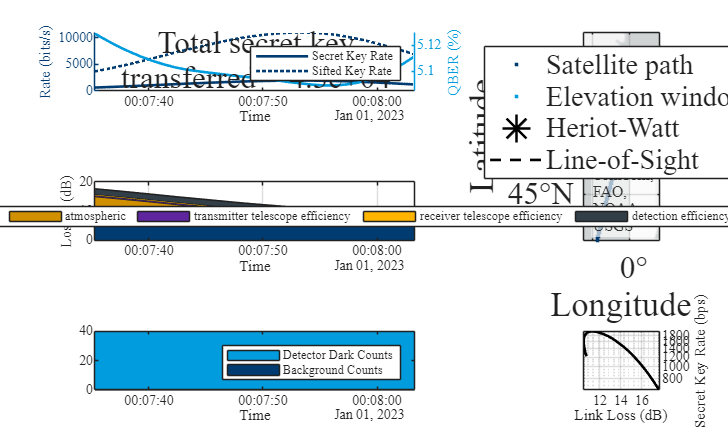

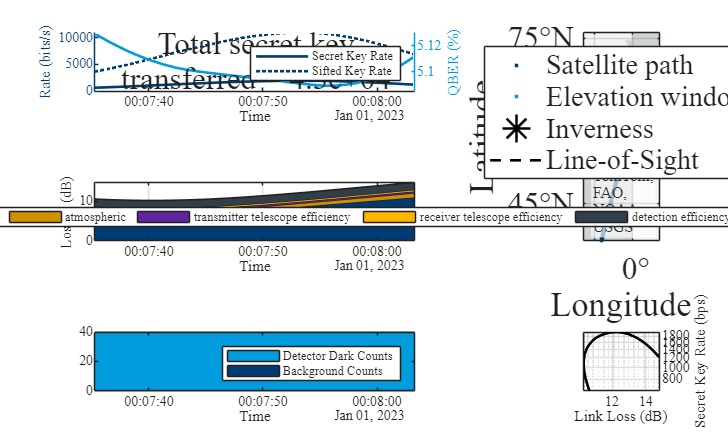

for result = results
    result.plot();
end